# Basic Genetic Algorithm Examples

#### Prepared by: Yuanfei Wang

#### Date: 03 July 2022

clc
clear
close all

### Example 1

Optimize a nonsmooth function using ga.

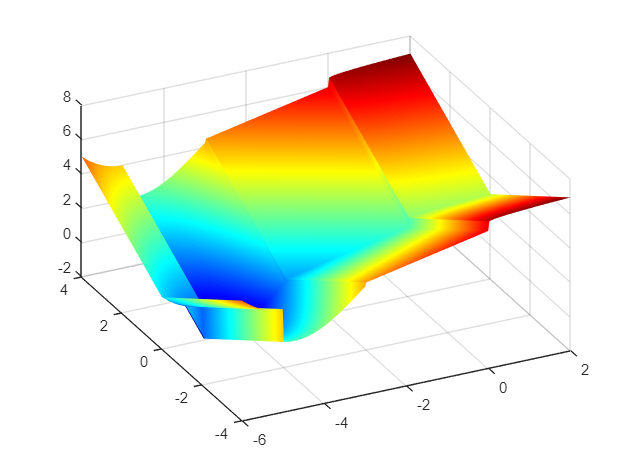

%
xi = linspace(-6,2,300);
yi = linspace(-4,4,300);
[X,Y] = meshgrid(xi,yi);
Z = ps_example([X(:),Y(:)]);
Z = reshape(Z,size(Y));
surf(X,Y,Z,'MeshStyle','none')
colormap jet
view(-26,43)

rng default
[x, fval] = ga(@ps_example,2); % nvars (2 in this example) is the dimension (number of design variables) of fun.

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


fprintf('The x value is %.4f and %.4f, the f value is %.4f',x,fval);

The x value is -4.6793 and -0.0860, the f value is -1.9129

### Example 2

Optimize ga with inequal constraints.

% x(1)+x(2)>=1, x(2)<=5+x(1)
A = [-1,-1;-1,1];
b = [-1;5];
[x, fval] = ga(@ps_example,2,A,b);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


disp(A*x'-b)

    0.0010
   -5.9990



fprintf('The x value is %.4f and %.4f, the f value is %.4f',x,fval);

The x value is 0.9990 and -0.0000, the f value is 2.7999

### Example 3

Optimize ga with equal and inequal constraints.

% x(1)+x(2)>=1, x(2)==5+x(1)
A = [-1, -1];
b = [-1];
Aeq = [-1, 1];
beq = 5;
[x, fval] = ga(@ps_example,2,A,b,Aeq,beq);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


fprintf('The x value is %.4f and %.4f, the f value is %.4f',x,fval);

The x value is -2.0000 and 2.9990, the f value is 3.9990

### Example 4

Optimize ga with bound constraints.

% x(1)+x(2)>=1, x(2)==5+x(1)
A = [-1, -1];
b = [-1];
Aeq = [-1, 1];
beq = 5;
lb = [1, -3];
ub = [6, 8];
[x, fval] = ga(@ps_example,2,A,b,Aeq,beq,lb,ub);

Optimization terminated: average change in the fitness value less than options.FunctionTolerance.


fprintf('The x value is %.4f and %.4f, the f value is %.4f',x,fval);

The x value is 1.0000 and 5.9990, the f value is 8.7990

disp(A*x'-b);

   -5.9990



disp(Aeq*x'-beq);

  -9.8908e-04



type ps_example.m

function f = ps_example(x)
%PS_EXAMPLE objective function for pattern search.

%   Copyright 2003-2004 The MathWorks, Inc.


for i = 1:size(x,1)
    if  x(i,1) < -5
        f(i) = (x(i,1)+5)^2 + abs(x(i,2));
    elseif x(i,1) < -3
        f(i) = -2*sin(x(i,1)) + abs(x(i,2));
    elseif x(i,1) < 0
        f(i) = 0.5*x(i,1) + 2 + abs(x(i,2));
    elseif x(i,1) >= 0
        f(i) = .3*sqrt(x(i,1)) + 5/2 +abs(x(i,2));
    end
end






### Example 5

Optimize ga with nonlinear constraints.

Optimization terminated: average change in the fitness value less than options.FunctionTolerance
 and constraint violation is less than options.ConstraintTolerance.


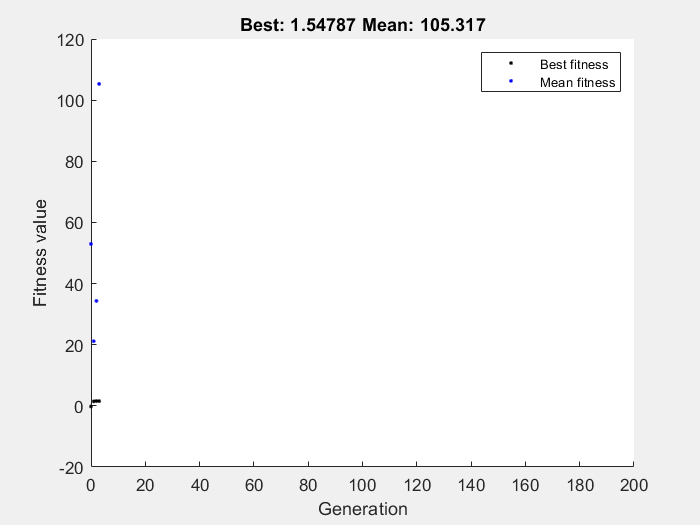

% nonlinear constraints can not be transferred to the Ax <=/== b form, 
rng default
options = optimoptions("ga","ConstraintTolerance",1e-3,"PlotFcn","gaplotbestf");
[x, fval] = ga(@ps_example,2,[],[],[],[],[],[],@elipsecons,options);

fprintf('The x value is %.4f and %.4f, the f value is %.4f',x,fval);

The x value is -0.9766 and 0.0362, the f value is 1.5479

[c, ceq] = elipsecons(x);
fprintf('The c value is %.4f and ceq value is %.4f',c,ceq);

The c value is -1.0911 and ceq value is 0.0005

### Example 6

Optimize ga with integer constraints.

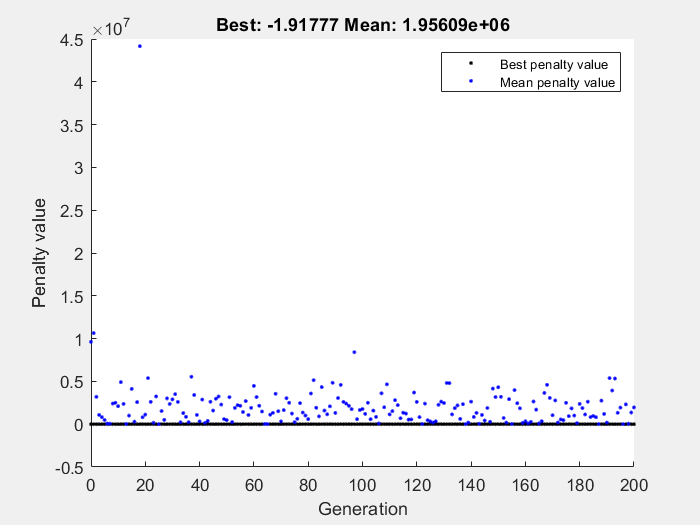

Optimization terminated: maximum number of generations exceeded.


% x(1)+x(2)>=1, x(2)==5+x(1)
A = [];
b = [];
Aeq = [];
beq = [];
lb = [];
ub = [];
intcon = 1;
[x, fval, exitflag, output, population, scores] = ga(@ps_example,2,A,b,Aeq,beq,lb,ub,[],intcon,options);

fprintf('The x value is %.4f and %.4f, the f value is %.4f, exitflag is %.4f',x,fval,exitflag);

The x value is -5.0000 and 0.0001, the f value is -1.9178, exitflag is 0.0000

[c, ceq] = elipsecons(x);
fprintf('The c value is %.4f and ceq value is %.4f',c,ceq);

The c value is 47.0000 and ceq value is 16.0000

### Example 7

Vectorized function.

VFitness_function = @(x) vectorized_fitness(x,100,1);
options = optimoptions('ga','UseVectorized',true,'ConstraintTolerance',1e-6);
lb = [-3, -3];
ub = [3, 3];
[x, fval] = ga(VFitness_function,2,[],[],[],[],lb,ub,[],options);

Optimization terminated: maximum number of generations exceeded.


function [c, ceq] = elipsecons(x)
c = 2*x(1)^2+x(2)^2-3;
ceq = (x(1)+1)^2 - (x(2)/2)^4;
end